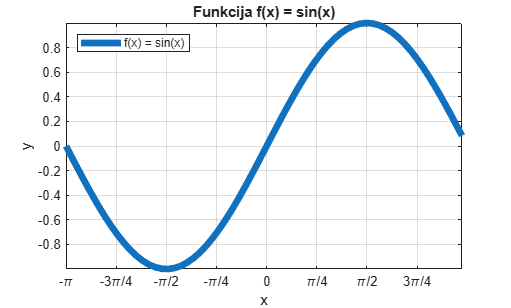

%Gustas Neverdauskas EAf-25 LAB3 2026.10.09

%1uzd

x = -pi:0.1:pi;

figure(1) 
y1 = sin(x);
plot(x, y1, 'LineWidth', 5)

title('Funkcija f(x) = sin(x)')
xlabel('x')
ylabel('y')
axis([min(x) max(x) min(y1) max(y1)])
legend('f(x) = sin(x)', 'Location', 'northwest')
grid on 

xticks(-pi:pi/4:pi)
xticklabels({'-\pi', '-3\pi/4', '-\pi/2', '-\pi/4', '0', '\pi/4', '\pi/2', '3\pi/4', '\pi'})

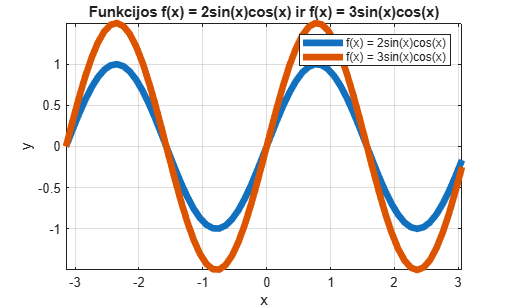



figure(2)
y21 = 2*sin(x).*cos(x);
y22 = 3*sin(x).*cos(x);

plot(x, y21, 'LineWidth', 5)
hold on
plot(x, y22, 'LineWidth', 5)
hold off

title('Funkcijos f(x) = 2sin(x)cos(x) ir f(x) = 3sin(x)cos(x)')
xlabel('x')
ylabel('y')

y_all = [y21, y22];
axis([min(x) max(x) min(y_all) max(y_all)])

legend('f(x) = 2sin(x)cos(x)', 'f(x) = 3sin(x)cos(x)') 
grid on

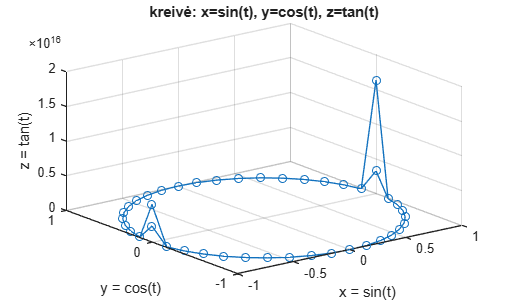

%2uzd
clear all;

t = 0 : pi/20 : 4*pi;

x = sin(t);
y = cos(t);
z = tan(t);

figure;
plot3(x, y, z, '-o')

title('kreivė: x=sin(t), y=cos(t), z=tan(t)');
xlabel('x = sin(t)');
ylabel('y = cos(t)');
zlabel('z = tan(t)');

grid on;

%papildoma
clear all;

%senas info
A = 5;
f = 6;
sigma = 1.5;
U1 = 3;
U2 = 2;
t = 0:0.002:1.2;

st = A * sin(2*pi*f*t) + 0.5 * A * cos(4*pi*f*t)

st =     2.5000    2.8483    3.1383    3.3699    3.5440    3.6630    3.7302    3.7499    3.7274    3.6685    3.5797    3.4679    3.3402    3.2035    3.0648    2.9306    2.8068    2.6988    2.6111    2.5472    2.5098    2.5004    2.5193    2.5657    2.6378    2.7327    2.8465    2.9744    3.1109    3.2496    3.3841    3.5073    3.6122    3.6918    3.7392    3.7483    3.7133    3.6293    3.4922    3.2991    3.0481    2.7386    2.3712    1.9478    1.4717    0.9473    0.3803   -0.2227   -0.8540   -1.5049


n = sigma * randn(size(t))

n =    -0.8055   -1.5602    1.4959   -0.0391   -0.9855    1.0166   -0.7663    0.6690    2.2750    1.4066   -0.2402   -0.1708    2.9057   -0.2562    0.4518    0.4890    1.3873    0.3229    0.5494    0.4832    4.0335    1.3141   -1.3147   -1.8262   -2.4223    2.7601   -1.2284    1.4882    0.8007   -2.2901    3.0343    0.8284    2.7302    0.5140    0.2693   -1.5290    0.0564    0.2057   -2.2816   -0.0284    0.2449   -1.0817    0.6159   -1.8189   -0.8606    0.1581   -0.9076    0.6327   -0.5442   -1.3112


s = st + n

s =     1.6945    1.2880    4.6342    3.3308    2.5585    4.6797    2.9640    4.4189    6.0023    5.0751    3.3395    3.2972    6.2459    2.9473    3.5166    3.4196    4.1940    3.0217    3.1604    3.0305    6.5434    3.8145    1.2045    0.7395    0.2156    5.4929    1.6182    4.4626    3.9116    0.9596    6.4184    4.3358    6.3424    4.2057    4.0086    2.2194    3.7697    3.8350    1.2107    3.2708    3.2930    1.6569    2.9871    0.1289    0.6111    1.1054   -0.5274    0.4100   -1.3982   -2.8161



virsija_U1 = s(s>U1)

virsija_U1 =     4.6342    3.3308    4.6797    4.4189    6.0023    5.0751    3.3395    3.2972    6.2459    3.5166    3.4196    4.1940    3.0217    3.1604    3.0305    6.5434    3.8145    5.4929    4.4626    3.9116    6.4184    4.3358    6.3424    4.2057    4.0086    3.7697    3.8350    3.2708    3.2930    3.5466    4.8023    3.6653    5.5896    3.4861    4.2948    6.0030    4.2975    3.4947    4.0906    3.1276    6.4991    4.9140    4.2046    3.3680    4.5179    4.5521    6.2052    4.1025    3.5026    3.4292



s2 = s

s2 =     1.6945    1.2880    4.6342    3.3308    2.5585    4.6797    2.9640    4.4189    6.0023    5.0751    3.3395    3.2972    6.2459    2.9473    3.5166    3.4196    4.1940    3.0217    3.1604    3.0305    6.5434    3.8145    1.2045    0.7395    0.2156    5.4929    1.6182    4.4626    3.9116    0.9596    6.4184    4.3358    6.3424    4.2057    4.0086    2.2194    3.7697    3.8350    1.2107    3.2708    3.2930    1.6569    2.9871    0.1289    0.6111    1.1054   -0.5274    0.4100   -1.3982   -2.8161


s2(abs(s2)<U2) = 0

s2 =          0         0    4.6342    3.3308    2.5585    4.6797    2.9640    4.4189    6.0023    5.0751    3.3395    3.2972    6.2459    2.9473    3.5166    3.4196    4.1940    3.0217    3.1604    3.0305    6.5434    3.8145         0         0         0    5.4929         0    4.4626    3.9116         0    6.4184    4.3358    6.3424    4.2057    4.0086    2.2194    3.7697    3.8350         0    3.2708    3.2930         0    2.9871         0         0         0         0         0         0   -2.8161



nefiltruotas_dydis = length(s)

nefiltruotas_dydis = 601


atrinktu_dydis = length(virsija_U1)

atrinktu_dydis = 187


maxs2 = max(s2)

maxs2 = 6.8992

mins2 = min(s2)

mins2 = -10.2015

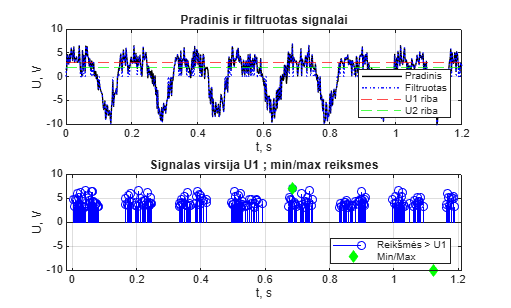


%ATNAUJINTA

figure;
subplot(2,1,1);
plot(t, s, 'k-', t, s2, 'b:', 'LineWidth', 1);
hold on;
yline(U1, 'r--');
yline(U2, 'g--');
hold off;
title('Pradinis ir filtruotas signalai');
xlabel('t, s'); ylabel('U, V');
grid on;
legend('Pradinis', 'Filtruotas', 'U1 riba', 'U2 riba', 'Location', 'southeast');

subplot(2,1,2);
stem(t(s > U1), s(s > U1), 'b');
hold on;
plot(t(s==max(s)), max(s), 'gd', t(s==min(s)), min(s), 'gd', 'MarkerFaceColor', 'g');
hold off;
title('Signalas virsija U1 ; min/max reiksmes');
xlabel('t, s'); ylabel('U, V');
grid on;
legend('Reikšmės > U1', 'Min/Max', 'Location', 'southeast');